%compare beam squint compensation between different method
clc;
clear all;
close all;

NantTX = [256];

%% system parameters
Sysparam = struct();

%Sysparam.Nt = 256;
Sysparam.Nr = 4;
Sysparam.Ns = 4;
Sysparam.fc = 3e11;%carrier frequency 
Sysparam.f = 30e9; %bandwidth 
Sysparam.K = 129;  %number of sub-carriers
Sysparam.M = 16; %number of TTDs for each RF chain
Sysparam.L = 1 ; % number of paths equals to number of RF chains
% compute discrete time-delay values
Sysparam.Q = 16; % number of fixed TTD element 
Sysparam.tmax = (1e-12)*340;
Sysparam.T = Sysparam.tmax*(0:1:Sysparam.Q-1)/(Sysparam.Q-1);
%% Sub-carrier frequencies
for k =1:Sysparam.K 
    Sysparam.F(k,1) = Sysparam.fc +(Sysparam.f/Sysparam.K)*(k-1-(Sysparam.K-1)/2); % sub-carrier frequency
end 
% relative frequencies
Sysparam.xi = Sysparam.F/Sysparam.fc; 

%% simulation parameters
Simparam = struct();

Simparam.psi = pi*rand(Sysparam.L,1)-0.5*pi; %AoA;
%Simparam.P = -20:5:15;% transmit power in dB
%Simparam.Rho = 10.^(Simparam.P/10); %transmit power
Simparam.Niter = 50; %channel realizations
Simparam.phi = 0.2951*pi*ones(Sysparam.L,1);%AoD;
SpatialDirection = sin(Simparam.phi)

SpatialDirection = 0.7999

Nloop = 50;

%% 
for i = 1:length(NantTX)
     
Sysparam.Nt = NantTX(i);% maximum time-delay value
Sysparam.N = Sysparam.Nt/Sysparam.M; %number of PSs for each TTD
%Generate wideband channel
H = WidebandChannel(Sysparam,Simparam);
[G1,G2k,x2,t2] = fixPSdesignTTD(Sysparam,Simparam); %Tan design
[PS,TTD,x,t] = jointPSandTTD(Sysparam, Simparam); % joint delay and phase precoding
%[S,F2k,D,~] = DynamicSubarray(Sysparam,Simparam,H,Nloop); %Dynamic subarray method
[F1,F2k,x_Gao,TTD_Gao] = Gao_fixedPS_TD(Sysparam,Simparam);
for l = 1:Sysparam.L
    a(:,l) = arrayResponse(sin(Simparam.phi(l)),Sysparam.Nt);
    for k = 1:Sysparam.K
         b(:,k,l) = arrayResponse(Sysparam.xi(k)*sin(Simparam.phi(l)),Sysparam.Nt);
         arrayGain(k,l,i) = abs(a(:,l)'*b(:,k,l));
         Compensated1(k,l,i) = abs((PS*TTD(:,l,k))'*b(:,k,l));
         Compensated2(k,l,i) = abs((G1*G2k(:,l,k))'*b(:,k,l));          
         Compensated3(k,l,i) = abs((F1*F2k(:,l,k))'*b(:,k,l));
    end
end
clear a b ;
end 

%%
set(0, 'defaultlinelinewidth', 3); set(0, 'defaultlinemarkersize', 8);
set(0, 'defaultaxesfontsize', 20); set(0, 'defaulttextfontsize', 20); 

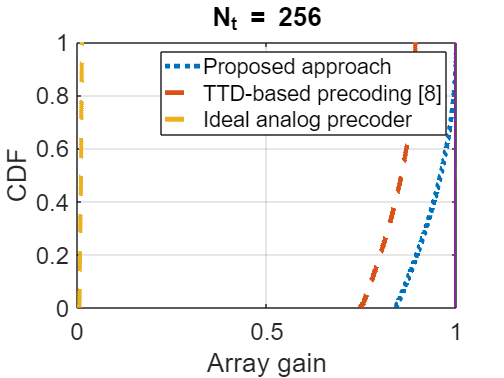

close all;
figure(1)
f1 = cdfplot(Compensated1(:,:,1));
set(f1,'LineWidth',4,'LineStyle',':','Marker','none');
hold on
f2 = cdfplot(Compensated2(:,:,1));
set(f2,'LineWidth',4,'LineStyle','--','Marker','none');
hold on
f3 = cdfplot(Compensated3(:,:,1));
set(f3,'LineWidth',4,'LineStyle','--','Marker','none');
hold on
f4 = cdfplot(ones(Sysparam.K,1));
set(f4,'LineWidth',4,'LineStyle','-','Marker','none');
legend('Proposed approach','TTD-based precoding [8]','Ideal analog precoder')
xlabel('Array gain')
ylabel('CDF')
title('N_t = 256')

% figure(2)
% f1 = cdfplot(Compensated1(:,:,2));
% set(f1,'LineWidth',4,'LineStyle',':','Marker','none');
% hold on
% f2 = cdfplot(Compensated2(:,:,2));
% set(f2,'LineWidth',4,'LineStyle','--','Marker','none');
% hold on
% % f3 = cdfplot(Compensated3(:,:,2));
% % set(f3,'LineWidth',4,'LineStyle','--','Marker','none');
% % hold on
% f4 = cdfplot(ones(Sysparam.K,1));
% set(f4,'LineWidth',4,'LineStyle','-','Marker','none');
% legend('Proposed approach','TTD-based precoding [8]','Ideal analog precoder')
% xlabel('Array gain')
% ylabel('CDF')
% title('N_t = 256')
% figure(3)
% f1 = cdfplot(Compensated1(:,:,3));
% set(f1,'LineWidth',4,'LineStyle',':','Marker','none');
% hold on
% f2 = cdfplot(Compensated2(:,:,3));
% set(f2,'LineWidth',4,'LineStyle','--','Marker','none');
% hold on
% % f3 = cdfplot(Compensated3(:,:,3));
% % set(f3,'LineWidth',4,'LineStyle','--','Marker','none');
% hold on
% f4 = cdfplot(ones(Sysparam.K,1));
% set(f4,'LineWidth',4,'LineStyle','-','Marker','none');
% legend('Proposed approach','TTD-based precoding [8]','Ideal analog precoder')
% xlabel('Array gain')
% ylabel('CDF')
% title("N_t = 512")